clear all;
% parameter
N_fft = 64;
N_CP = 16;
Fs = 10e6;

all_sc = [-26:-1 1:26];                 % i.e.[-26, -25, ..., -1, 1, 2, ..., 26]
pilots = [-21 -7 7 21];                 % pilot tones
data_sc = setdiff(all_sc, pilots);      % 48 data tones                
toPos = @(k) mod(k, N_fft) + 1;         

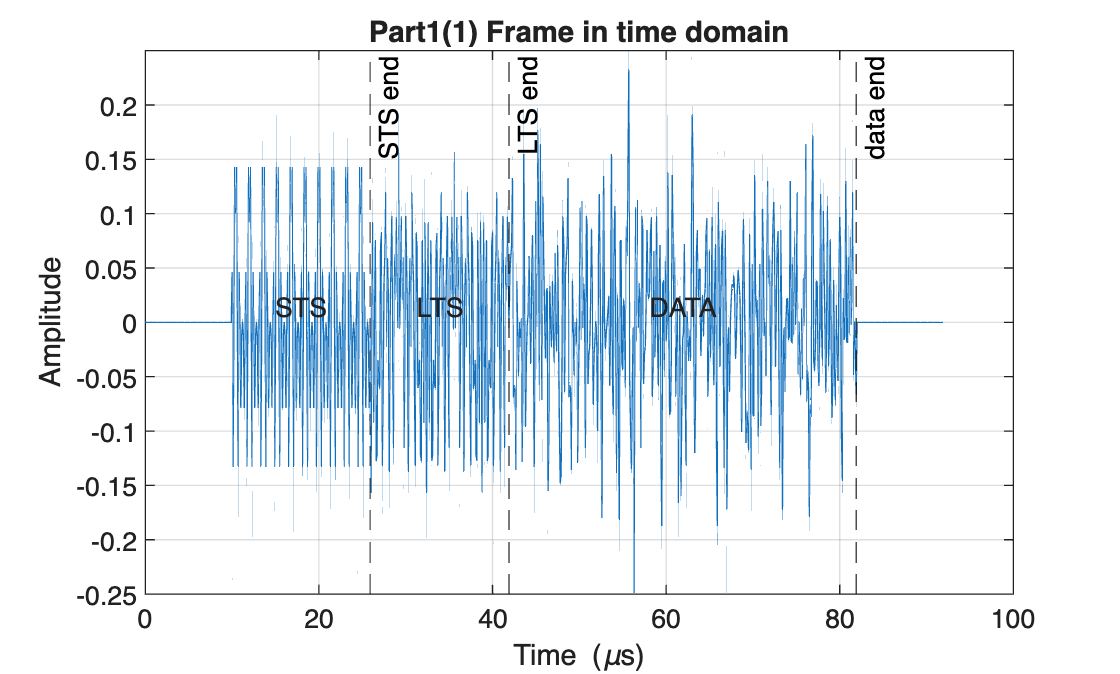

% Part1(1)
% STS
S_used = sqrt(13/6) * [0, 0, 1+1j, 0, 0, 0, -1-1j, 0, 0, 0, 1+1j, 0, 0, 0, -1-1j, 0, 0, 0, -1-1j, 0, 0, 0, 1+1j, ...
        0, 0, 0, 0 ,0, 0, -1-1j, 0, 0, 0, -1-1j, 0, 0, 0, 1+1j, 0, 0, 0, 1+1j, 0, 0, 0, 1+1j, 0, 0, 0, 1+1j, 0, 0];
X_sts = zeros(1, N_fft);
X_sts(toPos(all_sc)) = S_used;   

x_sts64 = ifft(X_sts, N_fft);       
x_short = x_sts64(1:16);         
x_STS_10 = repmat(x_short, 1, 10);

% LTS
L_used = [1,1,-1,-1,1,1,-1,1,-1,1,1,1,1,1,1,-1,-1,1,1,-1,1,-1,1,1,1,1,1,...
            -1,-1,1,1,-1,1,-1,1,-1,-1,-1,-1,-1,1,1,-1,-1,1,-1,1,-1,1,1,1,1] ;   

X_lts = zeros(1, N_fft);
X_lts(toPos(all_sc)) = L_used;

x_LTS = ifft(X_lts, N_fft);     
                
LTS_block = [x_LTS(end-2*N_CP+1:end), x_LTS, x_LTS]; 
M = 4;
numDataSym = 5;
frame_data = [];
txBits = cell(1, numDataSym); 
pilotSym  = cell(1, numDataSym);
txSymTone = cell(1, numDataSym);  
txSymAll  = [];                    

% 5 OFDM symbol
for nSym = 1:numDataSym

    Xd = zeros(1, N_fft);
    % pilot: random BPSK
    pilot_bits = randi([0 1], 1, 4);
    pilot_sym  = 1 - 2*pilot_bits;
    Xd(toPos(pilots)) = pilot_sym;
    pilotSym{nSym}    = pilot_sym(:); 

    % data: 4-QAM 
    data_bits = randi([0 1], 48*log2(M), 1);
    txBits{nSym} = data_bits;
    data_sym  = qammod(data_bits, M, 'InputType','bit', 'UnitAveragePower', true);
    Xd(toPos(data_sc)) = data_sym.';
    txSymTone{nSym} = data_sym(:);        
    txSymAll = [txSymAll; data_sym(:)];   

    x_noCP = ifft(Xd, N_fft);
    x_CP   = [x_noCP(end-N_CP+1:end), x_noCP];
    frame_data = [frame_data, x_CP]; 
 
end



Pre_pad = zeros(1,100);
Post_pad = zeros(1,100);

tx_frame = [Pre_pad, x_STS_10, LTS_block, frame_data, Post_pad];

t_frame_us = (0:numel(tx_frame)-1)/Fs*1e6;
i1 = numel(Pre_pad) + numel(x_STS_10);
i2 = i1 + numel(LTS_block);
i3 = i2 + numel(frame_data);

figure;
plot(t_frame_us, real(tx_frame)); 
xline(t_frame_us(i1), '--k', 'STS end'); 
xline(t_frame_us(i2), '--k', 'LTS end');
xline(t_frame_us(i3), '--k', 'data end');
grid on; xlabel('Time (\mus)'); ylabel('Amplitude');
ylim([-0.25 0.25]);
title('Part1(1) Frame in time domain');
text(t_frame_us(round(i1-numel(x_STS_10)/2)), 0, 'STS','HorizontalAlignment','center','VerticalAlignment','bottom');
text(t_frame_us(round((i1+i2)/2)), 0, 'LTS','HorizontalAlignment','center','VerticalAlignment','bottom');
text(t_frame_us(round(i2+numel(frame_data)/2)), 0, 'DATA','HorizontalAlignment','center','VerticalAlignment','bottom');

% Part1(2)
% Initialize USRP
tx_frame_all=[];
for i = 1:100
    tx_frame_all = [tx_frame_all, tx_frame];
end
rx_length = 2*length(tx_frame) ; % Set receive buffer size to match transmitted frame
[radio_Tx, radio_Rx] = USRP_init(rx_length);
radio_Tx.InterpolationFactor = 10;
radio_Rx.DecimationFactor = 10;
N_frames = 10;
threshold = 0.002;
N_trans = 2000;
rx_buffer = zeros(N_frames ,rx_length) ;
rx_buffer_all = [];
count = 0;
for k = 1:N_trans
    tunderrun = radio_Tx(tx_frame(:));       % send k-th signal
    [rx_frame, ~, toverflow] = step(radio_Rx); % receive signal

    Power = mean(abs(rx_frame).^2);
    if Power > threshold
        count = count + 1;
        rx_buffer(count,:) = rx_frame.'; % save the signal to buffer
        rx_buffer_all = [rx_buffer_all, rx_buffer(count,:)];
    end
    if count == N_frames
        break;
    end
end

release(radio_Tx);
release(radio_Rx);

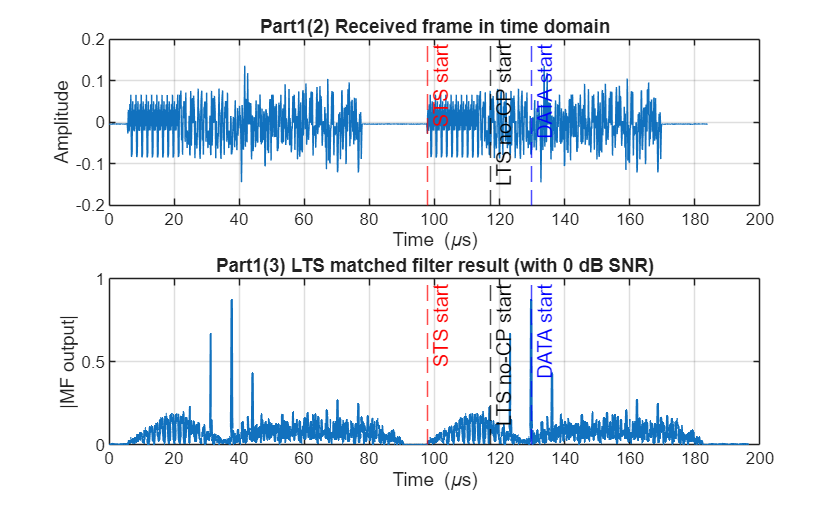

% Part1(3)
f = rx_buffer(5,:);
% P_f = mean(abs(f).^2);
% fprintf('Power of signal = %f', P_f);
LEN_STS = numel(x_STS_10); % 160
LEN_LTS_noCP  = numel(LTS_block) - 2*N_CP;  % 128    

lts2_tmpl = tx_frame(i1 + 2*N_CP + (1:LEN_LTS_noCP)).'; 
h_mf = conj(flipud(lts2_tmpl));
mf  = conv(f(:), h_mf, 'full');  
a = abs(mf);
[~, pk] = max(a);

start_LTS_noCP = pk - (numel(lts2_tmpl) - 1);  
start_STS      = start_LTS_noCP - LEN_STS - 2*N_CP;    
start_DATA     = start_LTS_noCP + LEN_LTS_noCP;   

t_mf_us = (0:numel(mf)-1)/Fs*1e6;
t = (0:length(f)-1) * (1e6/Fs); % Convert to microseconds

figure;
subplot(2,1,1);
plot(t, real(f));
xlabel('Time (\mus)'); ylabel('Amplitude');
title('Part1(2) Received frame in time domain');
xline(start_STS     /Fs*1e6,'--r','STS start');
xline((start_LTS_noCP)/Fs*1e6,'--k','LTS no-CP start');
xline(start_DATA    /Fs*1e6,'--b','DATA start');
grid on;

subplot(2,1,2);
% figure('Name','(9) LTS-based MF @ 0 dB');
plot(t_mf_us, a, 'LineWidth', 1.2); grid on;
xlabel('Time (\mus)'); ylabel('|MF output|');
title('Part1(3) LTS matched filter result (with 0 dB SNR)');
xline(start_STS     /Fs*1e6,'--r','STS start');
xline((start_LTS_noCP)/Fs*1e6,'--k','LTS no-CP start');
xline(start_DATA    /Fs*1e6,'--b','DATA start');

% Part1(4)
fprintf('The index marks the beginning of the first long training symbol is %d.',start_LTS_noCP);

The index marks the beginning of the first long training symbol is 1171.

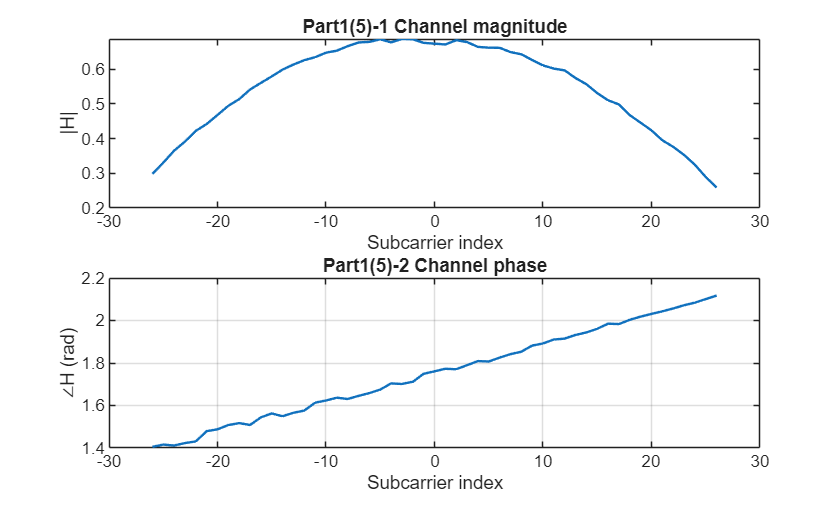

% Part1(5)
rx_lts_1 = f(start_LTS_noCP + (0:numel(x_LTS)-1));
Rx_LTS_1 = fft(rx_lts_1, N_fft);
H_LTS1 = Rx_LTS_1 ./ X_lts;  

figure;
subplot(2,1,1);
plot(all_sc, abs(H_LTS1(toPos(all_sc))), 'LineWidth',1.2);
xlabel('Subcarrier index'); ylabel('|H|');
title('Part1(5)-1 Channel magnitude');

subplot(2,1,2);
plot(all_sc, angle(H_LTS1(toPos(all_sc))), 'LineWidth',1.2);
xlabel('Subcarrier index'); ylabel('∠H (rad)');
title('Part1(5)-2 Channel phase');
grid on;

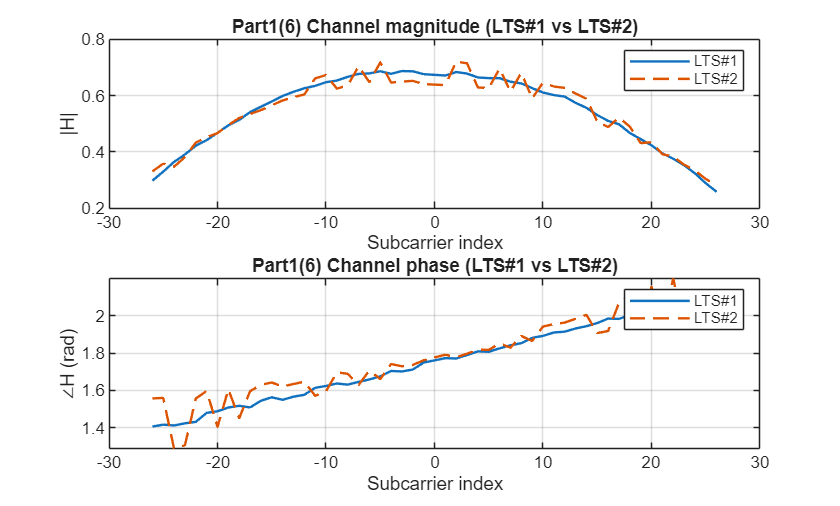

% Part1(6)
rx_lts_2 = f(start_LTS_noCP + numel(x_LTS) + (0:numel(x_LTS)-1));
Rx_LTS_2 = fft(rx_lts_2, N_fft);
H_LTS2   = Rx_LTS_2 ./ X_lts;

figure;
subplot(2,1,1);
plot(all_sc, abs(H_LTS1(toPos(all_sc))), 'LineWidth',1.2); hold on;
plot(all_sc, abs(H_LTS2(toPos(all_sc))), '--', 'LineWidth',1.2);
xlabel('Subcarrier index'); ylabel('|H|');
title('Part1(6) Channel magnitude (LTS#1 vs LTS#2)');
legend('LTS#1','LTS#2'); grid on;

subplot(2,1,2);
plot(all_sc, angle(H_LTS1(toPos(all_sc))), 'LineWidth',1.2); hold on;
plot(all_sc, angle(H_LTS2(toPos(all_sc))), '--', 'LineWidth',1.2);
xlabel('Subcarrier index'); ylabel('∠H (rad)');
title('Part1(6) Channel phase (LTS#1 vs LTS#2)');
legend('LTS#1','LTS#2'); grid on;

% Part1(7)


$$\Delta f = \frac{F_s}{N} = \frac{10^6}{64} = 156.125kHz\\
\text{Frequency carried by subcarrier -26: }  f_c - 26\Delta f = 880.9375MHz\\
\text{Frequency carried by subcarrier 0: }  f_c = 885MHz\\
\text{Frequency carried by subcarrier +26: }  f_c + 26\Delta f = 889.0625MHz\\$$


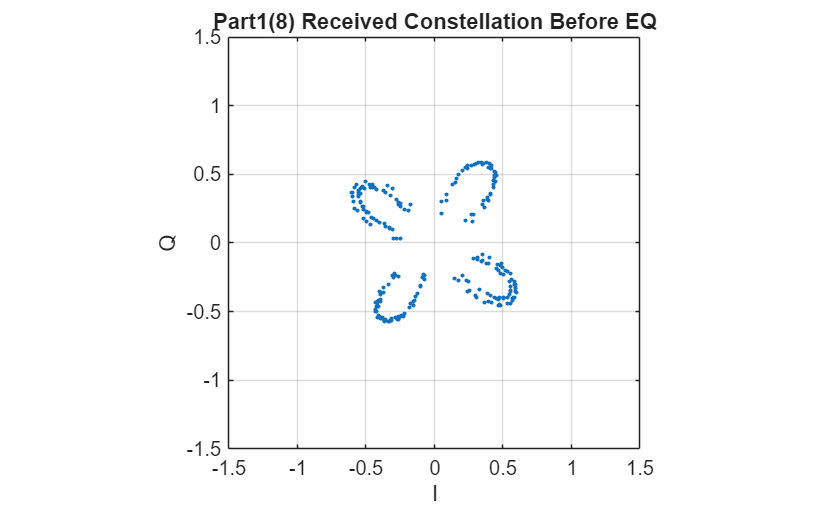

% Part1(8)
LEN_SYM_CP = N_fft + N_CP;
idx_data_blk = start_DATA + (0:LEN_SYM_CP*numDataSym-1);
rx_blk = f(idx_data_blk);
rx_sym_mat = reshape(rx_blk, LEN_SYM_CP, numDataSym).';
rx_noCP = rx_sym_mat(:, N_CP+1:end);
Y_beforeEQ = []; 

for m = 1:numDataSym
    rx_sym = rx_noCP(m, :);             
    Y = fft(rx_sym, N_fft);
    Yd = Y(toPos(data_sc)).';
    Y_beforeEQ = [Y_beforeEQ; Yd];
end

figure;
plot(real(Y_beforeEQ), imag(Y_beforeEQ), '.'); title('Part1(8) Received Constellation Before EQ'); axis equal; grid on;
xlabel('I'); ylabel('Q');xlim([-1.5 1.5]); ylim([-1.5 1.5]);

We observe that without equalization, the figure is not similar to 4-QAM. Hence, we may need equalization.

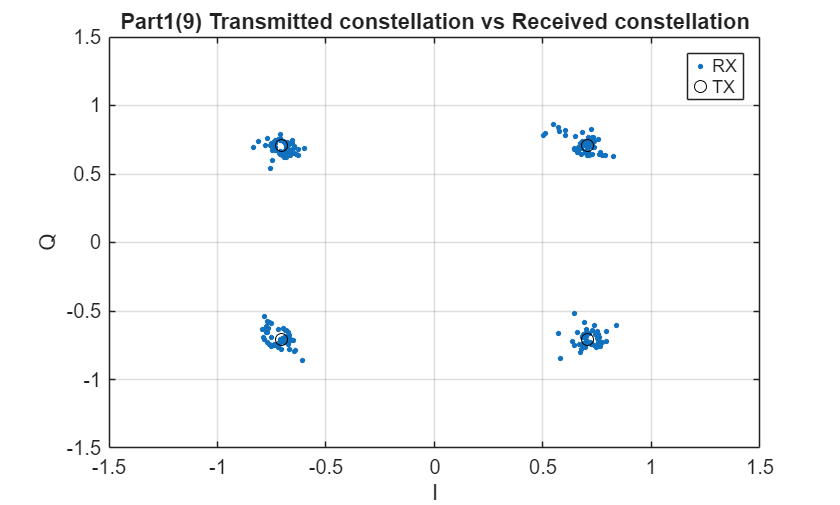

% Part1(9)
H_est = 0.5 * (H_LTS1 + H_LTS2);          
H_est_data = H_est(1, toPos(data_sc)).';    
Y_EQ = [];
for m = 1:numDataSym
    rx_sym = rx_noCP(m, :);             
    Y = fft(rx_sym, N_fft);
    Yd = Y(toPos(data_sc)).';
    Ye = Yd ./ H_est_data;
    Y_EQ = [Y_EQ; Ye];
end   
figure;
plot(real(Y_EQ), imag(Y_EQ), '.', 'MarkerSize',8); hold on; grid on;
xlabel('I'); ylabel('Q');xlim([-1.5 1.5]); ylim([-1.5 1.5]);

plot(real(txSymAll), imag(txSymAll), 'ok', 'MarkerFaceColor','none', 'MarkerSize',6);
legend('RX','TX');
xlabel('I'); ylabel('Q');
title('Part1(9) Transmitted constellation vs Received constellation');

% Part1(10)
sig_td = rx_blk;   

Npad = 100;   
noise_pre  = f(start_STS - 100:start_STS - 1);
noise_post = f(400 + start_DATA:500 + start_DATA);
noi_td = [noise_pre(:); noise_post(:)];

P_sig_tot = mean(abs(sig_td).^2);       
P_noi     = mean(abs(noi_td).^2);         

P_sig = max(P_sig_tot - P_noi, eps);     

SNR_dB = 10*log10(P_sig / P_noi);
fprintf('[Part1(10)] Estimated SNR = %.2f dB\n', SNR_dB);

[Part1(10)] Estimated SNR = 18.70 dB


fprintf('P_noi = %.9f', P_noi);

P_noi = 0.000052227

% Part1(11)
numFrameRepeat = 100;  % repeat transmission 100 times
numSym = 100;
BER_all = zeros(1, numFrameRepeat);

txBits = cell(1, numSym); 
pilotSym  = cell(1, numSym);
txSymTone = cell(1, numSym);  
txSymAll = [];
frame_data = [];
% ======== Generate TX ========   
for nSym = 1:numSym
    Xd = zeros(1, N_fft);
    % pilot: random BPSK
    pilot_bits = randi([0 1], 1, 4);
    pilot_sym  = 1 - 2*pilot_bits;
    Xd(toPos(pilots)) = pilot_sym;
    pilotSym{nSym}    = pilot_sym(:); 

    % data: 4-QAM 
    data_bits = randi([0 1], 48*log2(M), 1);
    txBits{nSym} = data_bits;
    data_sym  = qammod(data_bits, M, 'InputType','bit', 'UnitAveragePower', true);
    Xd(toPos(data_sc)) = data_sym.';
    txSymTone{nSym} = data_sym(:);        
    txSymAll = [txSymAll; data_sym(:)];   

    x_noCP = ifft(Xd, N_fft);
    x_CP   = [x_noCP(end-N_CP+1:end), x_noCP];
    frame_data = [frame_data, x_CP]; 
end
tx_frame = [Pre_pad, x_STS_10, LTS_block, frame_data, Post_pad];
% ======== RX =========

% Initialize USRP
rx_length = 2*length(tx_frame) + 2000 ; % Set receive buffer size to match transmitted frame
[radio_Tx, radio_Rx] = USRP_init(rx_length);
radio_Tx.InterpolationFactor = 10;
radio_Rx.DecimationFactor = 10;
N_frames = 100;
N_trans = 3000;
threshold = 0.002;
rx_buffer = zeros(N_frames,rx_length) ;
rx_buffer_all = [];
count = 0;
tic;
for j = 1:N_trans
    tunderrun = radio_Tx(tx_frame(:));       
    [rx_frame, ~, toverflow] = step(radio_Rx); 

    Power = mean(abs(rx_frame).^2);
    if Power > threshold
        count = count + 1;
        rx_buffer(count,:) = rx_frame.'; % save the signal to buffer
        rx_buffer_all = [rx_buffer_all, rx_buffer(count,:)];
    end

    if count == N_frames
        break;
    end
    if j == 100
        finish_time = toc;
    end
end

t = (0:length(rx_buffer)-1) * (1e6/Fs);

release(radio_Tx);
release(radio_Rx);
% ======== Start of data ========
i1 = numel(Pre_pad) + numel(x_STS_10);
lts2_tmpl = tx_frame(i1 + 2*N_CP + (1:LEN_LTS_noCP)).'; 
h_mf = conj(flipud(lts2_tmpl));
mf  = conv(rx_buffer_all(:), h_mf, 'full');  
a = abs(mf);
a_max = max(a);

pk = find(a >= 0.85);

for k = 1:100
    f = rx_buffer_all;
    start_LTS_noCP = pk(k) - (numel(lts2_tmpl) - 1);
    start_DATA  = pk(k) + 1;
    % fprintf('%d',k);
    % ======== Channel estimation ========
    rx_lts_1 = f(start_LTS_noCP + (0:numel(x_LTS)-1));
    Rx_LTS_1 = fft(rx_lts_1, N_fft);
    H_LTS1 = Rx_LTS_1 ./ X_lts;

    rx_lts_2 = f(start_LTS_noCP + numel(x_LTS) + (0:numel(x_LTS)-1));
    Rx_LTS_2 = fft(rx_lts_2, N_fft);
    H_LTS2   = Rx_LTS_2 ./ X_lts;

    H_est = 0.5 * (H_LTS1 + H_LTS2);          
    H_est_data = H_est(1, toPos(data_sc)).'; 
    % ======== Equalization ========
    idx_data_blk = start_DATA + (0:LEN_SYM_CP*numSym-1);
    rx_blk = f(idx_data_blk);
    rx_sym_mat = reshape(rx_blk, LEN_SYM_CP, numSym).';
    rx_noCP = rx_sym_mat(:, N_CP+1:end);
    Y_EQ = []; 

    for m = 1:numSym
        rx_sym = rx_noCP(m, :);             
        Y = fft(rx_sym, N_fft);
        Yd = Y(toPos(data_sc)).';
        Ye = Yd ./ H_est_data;
        Y_EQ = [Y_EQ; Ye];
    end
    % ======== Detection ========
    rxbits_all = qamdemod(Y_EQ, M, 'OutputType','bit', 'UnitAveragePower', true);
    txbits_all = [];
    for nSym = 1:numSym
        txbits_all = [txbits_all; qamdemod(txSymTone{nSym}, M, 'OutputType','bit', 'UnitAveragePower', true)]; 
    end
    BER_all(k) = mean(rxbits_all ~= txbits_all);
end
BER_avg = mean(BER_all);
fprintf('Part1(11) Average BER = %.9f\n', BER_avg);

Part1(11) Average BER = 0.008143750


% Part1(12)
fprintf('Transmission time = %f(s)\n', finish_time);

Transmission time = 9.026865(s)



$$\textrm{and}\;\textrm{there}\;\textrm{are}\;48\cdot 2\cdot 100\cdot 100=0\ldotp 96M\;\textrm{bits}\;\textrm{transmitted}\ldotp$$


% Part1(13)

1 transmission contains 4800 * 2 bits = 9600 bits


$$\begin{array}{l}
\frac{{10}^9 }{9600}=104166\ldotp 7,\textrm{thus}\;\textrm{we}\;\textrm{need}\;\textrm{to}\;\textrm{repeat}\;\textrm{the}\;\textrm{frame}\;\textrm{transmission}\;\textrm{for}\;\textrm{at}\;\textrm{least}\;104167\;\textrm{times}\;\textrm{to}\;\textrm{reach}\;\textrm{BER}\;{10}^{-9} \;\textrm{order}\;\textrm{precision}\ldotp \\
\textrm{The}\;\textrm{expected}\;\textrm{time}\;\textrm{is}\;\frac{9}{100}\cdot 104167=17960s\approx 2\ldotp 6\textrm{hr}\ldotp 
\end{array}$$
 

% Part1(14)
g_dB_list = 0:1:7;                 
g_list    = 10.^(g_dB_list/10);                         

BER_vsSNR = zeros(size(g_list));
SNRm_vsSNR = zeros(size(g_list));      
clip_flag = false(size(g_list));

txBits = cell(1, numSym); 
pilotSym  = cell(1, numSym);
txSymTone = cell(1, numSym);  
txSymAll = [];
frame_data = [];
% ======== Generate TX ========   
for nSym = 1:numSym
    Xd = zeros(1, N_fft);
    % pilot: random BPSK
    pilot_bits = randi([0 1], 1, 4);
    pilot_sym  = 1 - 2*pilot_bits;
    Xd(toPos(pilots)) = pilot_sym;
    pilotSym{nSym}    = pilot_sym(:); 

    % data: 4-QAM 
    data_bits = randi([0 1], 48*log2(M), 1);
    txBits{nSym} = data_bits;
    data_sym  = qammod(data_bits, M, 'InputType','bit', 'UnitAveragePower', true);
    Xd(toPos(data_sc)) = data_sym.';
    txSymTone{nSym} = data_sym(:);        
    txSymAll = [txSymAll; data_sym(:)];   

    x_noCP = ifft(Xd, N_fft);
    x_CP   = [x_noCP(end-N_CP+1:end), x_noCP];
    frame_data = [frame_data, x_CP]; 
end

for ig = 1:numel(g_dB_list)
    g = g_list(ig);
    numFrameRepeat = 100; 
    numSym = 100;
    BER_all = zeros(1, numFrameRepeat);
    SNR_acc = 0;
    % ======== Generate TX ========   
    tx_frame_g = [Pre_pad, x_STS_10, LTS_block, g*frame_data, Post_pad];
    % ======== RX =========

    % Initialize USRP
    rx_length = 2*length(tx_frame_g) + 2000; % Set receive buffer size to match transmitted frame
    [radio_Tx, radio_Rx] = USRP_init(rx_length);
    % radio_Tx.InterpolationFactor = 10;
    % radio_Rx.DecimationFactor = 10;
    N_frames = 150;
    N_trans = 3000;
    threshold = 0.002*g;
    rx_buffer = zeros(N_frames,rx_length) ;
    rx_buffer_all = [];
    count = 0;
    tic;
    for j = 1:N_trans
        tunderrun = radio_Tx(tx_frame_g(:));       
        [rx_frame, ~, toverflow] = step(radio_Rx); 
    
        Power = mean(abs(rx_frame).^2);
        is_whole = sum(abs(rx_frame) > 0.001);
        
        if Power > threshold && is_whole >= numel(tx_frame_g)
            count = count + 1;
            rx_buffer(count,:) = rx_frame.'; % save the signal to buffer
            rx_buffer_all = [rx_buffer_all, rx_buffer(count,:)];
        end
    
        if count == N_frames
            break;
        end
        if j == 100
            finish_time = toc;
        end
    end

    t = (0:length(rx_buffer)-1) * (1e6/Fs);
    release(radio_Tx);
    release(radio_Rx);
    % ======== Start of data ========
    i1 = numel(Pre_pad) + numel(x_STS_10);
    lts2_tmpl = tx_frame_g(i1 + 2*N_CP + (1:LEN_LTS_noCP)).';

    start_sts_index = zeros(200,1);
    n_success = 0;
    for k = 1:150
        f = rx_buffer(k,:);
        threshold_sts = 0.05;
        
        for i = 1 : numel(f)
            if abs(f(i))>threshold_sts
                start_sts_index(k) = i;
                break;
            end
        end
        start_LTS_noCP = start_sts_index(k) + 2*N_CP + LEN_STS;
        start_DATA = start_LTS_noCP + 2*numel(x_LTS);
        if start_DATA > numel(f) - LEN_SYM_CP*numSym - 100
            continue;
        end
       
        % ======== Channel estimation ========
        rx_lts_1 = f(start_LTS_noCP + (0:numel(x_LTS)-1));
        Rx_LTS_1 = fft(rx_lts_1, N_fft);
        H_LTS1 = Rx_LTS_1 ./ X_lts;

        rx_lts_2 = f(start_LTS_noCP + numel(x_LTS) + (0:numel(x_LTS)-1));
        Rx_LTS_2 = fft(rx_lts_2, N_fft);
        H_LTS2   = Rx_LTS_2 ./ X_lts;

        H_est = 0.5 * (H_LTS1 + H_LTS2);          
        H_est_data = H_est(1, toPos(data_sc)).'; 
        % ======== Equalization ========
        idx_data_blk = start_DATA + (0:LEN_SYM_CP*numSym-1);
        rx_blk = f(idx_data_blk);
        rx_sym_mat = reshape(rx_blk, LEN_SYM_CP, numSym).';
        rx_noCP = rx_sym_mat(:, N_CP+1:end);
        Y_EQ = []; 

        for m = 1:numSym
            rx_sym = rx_noCP(m, :);             
            Y = fft(rx_sym, N_fft);
            Yd = Y(toPos(data_sc)).';
            Ye = Yd ./ (g*H_est_data);
            Y_EQ = [Y_EQ; Ye];
        end
        % ======== Detection ========
        rxbits_all = qamdemod(Y_EQ, M, 'OutputType','bit', 'UnitAveragePower', true);
        txbits_all = [];
        for nSym = 1:numSym
            txbits_all = [txbits_all; qamdemod(txSymTone{nSym}, M, 'OutputType','bit', 'UnitAveragePower', true)]; 
        end
        BER_all(k) = mean(rxbits_all ~= txbits_all);
        %====== SNR ======
        sig_td = rx_blk;
        noi_td = [f(max(1,start_STS-100):start_STS-1), f(start_DATA+LEN_SYM_CP*numSym:min(numel(f), start_DATA+LEN_SYM_CP*numSym+99))];
        P_sig_tot = mean(abs(sig_td).^2);
        P_noi = mean(abs(noi_td).^2);
        P_sig = max(P_sig_tot - P_noi, eps);
        SNR_acc = SNR_acc + 10*log10(P_sig / P_noi);
        n_success = n_success + 1;
        if n_success == 100
            break;
        end
    end
    BER_vsSNR(ig)  = mean(BER_all);
    SNRm_vsSNR(ig) = SNR_acc / 100;
    fprintf('BER = %f, SNR = %.2fdB, gain = %.2f\n', BER_vsSNR(ig), SNRm_vsSNR(ig), g);
end

BER = 0.000000, SNR = 41.41dB, gain = 1.00
BER = 0.000000, SNR = 42.12dB, gain = 1.26
BER = 0.000000, SNR = 42.34dB, gain = 1.58
BER = 0.000000, SNR = 42.93dB, gain = 2.00
BER = 0.000000, SNR = 42.53dB, gain = 2.51
BER = 0.000250, SNR = 41.18dB, gain = 3.16
BER = 0.004221, SNR = 40.03dB, gain = 3.98
BER = 0.062633, SNR = 38.87dB, gain = 5.01


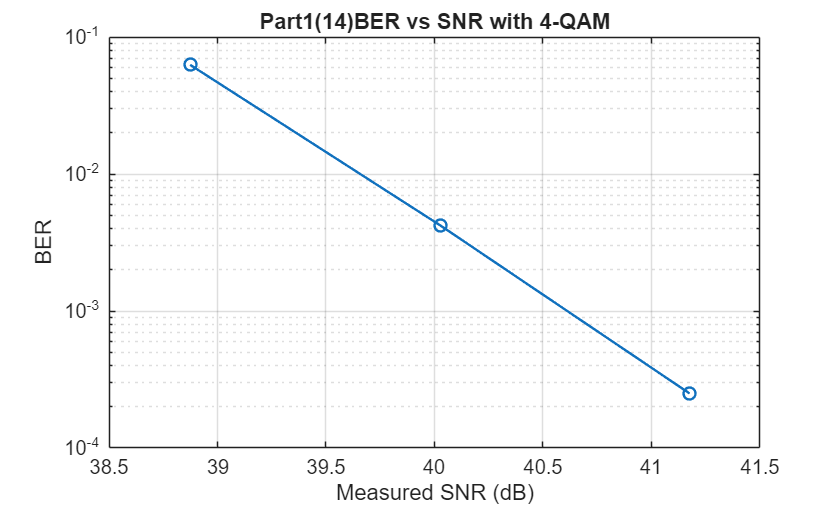

figure('Name','(14) BER vs SNR with clipping');
semilogy(SNRm_vsSNR, BER_vsSNR, 'o-','LineWidth',1.2); grid on;
xlabel('Measured SNR (dB)'); ylabel('BER'); title('Part1(14)BER vs SNR with 4-QAM');

As shown in the figure, the 4-QAM system achieves a BER of 0 when the transmit power gain is small. However, as the gain gradually increases to around 3, clipping occurs, and the BER is no longer zero. When the gain continues to increase, the BER worsens. The estimated SNR appears to decrease because the estimated noise power becomes inaccurate; in fact, it is oscillating rather than truly decreasing.

% Part1(15)
g_dB_list = 0:1:7;                 
g_list    = 10.^(g_dB_list/10);                         

BER_vsSNR = zeros(size(g_list));
SNRm_vsSNR = zeros(size(g_list));      
clip_flag = false(size(g_list));

txBits = cell(1, numSym); 
pilotSym  = cell(1, numSym);
txSymTone = cell(1, numSym);  
txSymAll = [];
frame_data = [];
% ======== Generate TX ========   
for nSym = 1:numSym
    Xd = zeros(1, N_fft);
    % pilot: random BPSK
    pilot_bits = randi([0 1], 1, 4);
    pilot_sym  = 1 - 2*pilot_bits;
    Xd(toPos(pilots)) = pilot_sym;
    pilotSym{nSym}    = pilot_sym(:); 

    % data: 16-QAM 
    data_bits = randi([0 1], 48*log2(16), 1);
    txBits{nSym} = data_bits;
    data_sym  = qammod(data_bits, 16, 'InputType','bit', 'UnitAveragePower', true);
    Xd(toPos(data_sc)) = data_sym.';
    txSymTone{nSym} = data_sym(:);        
    txSymAll = [txSymAll; data_sym(:)];   

    x_noCP = ifft(Xd, N_fft);
    x_CP   = [x_noCP(end-N_CP+1:end), x_noCP];
    frame_data = [frame_data, x_CP]; 
end


for ig = 1:numel(g_dB_list)
    g = g_list(ig);
    numFrameRepeat = 100; 
    numSym = 100;
    BER_all = zeros(1, numFrameRepeat);
    SNR_acc = 0;
    % ======== Generate TX ========   
    tx_frame_g = [Pre_pad, x_STS_10, LTS_block, g*frame_data, Post_pad];
    % ======== RX =========

    % Initialize USRP
    rx_length = 2*length(tx_frame_g) + 2000; 
    [radio_Tx, radio_Rx] = USRP_init(rx_length);
    % radio_Tx.InterpolationFactor = 10;
    % radio_Rx.DecimationFactor = 10;
    N_frames = 150;
    N_trans = 3000;
    threshold = 0.002*g;
    rx_buffer = zeros(N_frames,rx_length) ;
    rx_buffer_all = [];
    count = 0;
    tic;
    for j = 1:N_trans
        tunderrun = radio_Tx(tx_frame_g(:));       
        [rx_frame, ~, toverflow] = step(radio_Rx); 
    
        Power = mean(abs(rx_frame).^2);
        is_whole = sum(abs(rx_frame) > 0.001);
        
        if Power > threshold && is_whole >= numel(tx_frame_g)
            count = count + 1;
            rx_buffer(count,:) = rx_frame.'; % save the signal to buffer
            rx_buffer_all = [rx_buffer_all, rx_buffer(count,:)];
        end
    
        if count == N_frames
            break;
        end
        if j == 100
            finish_time = toc;
        end
    end

    t = (0:length(rx_buffer)-1) * (1e6/Fs);
    release(radio_Tx);
    release(radio_Rx);
    % ======== Start of data ========
    i1 = numel(Pre_pad) + numel(x_STS_10);
    lts2_tmpl = tx_frame_g(i1 + 2*N_CP + (1:LEN_LTS_noCP)).';

    start_sts_index = zeros(200,1);
    n_success = 0;
    for k = 1:150
        f = rx_buffer(k,:);
        threshold_sts = 0.05;
        
        for i = 1 : numel(f)
            if abs(f(i))>threshold_sts
                start_sts_index(k) = i;
                break;
            end
        end
        start_LTS_noCP = start_sts_index(k) + 2*N_CP + LEN_STS;
        start_DATA = start_LTS_noCP + 2*numel(x_LTS);
        if start_DATA > numel(f) - LEN_SYM_CP*numSym - 100
            continue;
        end
       
        % ======== Channel estimation ========
        rx_lts_1 = f(start_LTS_noCP + (0:numel(x_LTS)-1));
        Rx_LTS_1 = fft(rx_lts_1, N_fft);
        H_LTS1 = Rx_LTS_1 ./ X_lts;

        rx_lts_2 = f(start_LTS_noCP + numel(x_LTS) + (0:numel(x_LTS)-1));
        Rx_LTS_2 = fft(rx_lts_2, N_fft);
        H_LTS2   = Rx_LTS_2 ./ X_lts;

        H_est = 0.5 * (H_LTS1 + H_LTS2);          
        H_est_data = H_est(1, toPos(data_sc)).'; 
        % ======== Equalization ========
        idx_data_blk = start_DATA + (0:LEN_SYM_CP*numSym-1);
        rx_blk = f(idx_data_blk);
        rx_sym_mat = reshape(rx_blk, LEN_SYM_CP, numSym).';
        rx_noCP = rx_sym_mat(:, N_CP+1:end);
        Y_EQ = []; 

        for m = 1:numSym
            rx_sym = rx_noCP(m, :);             
            Y = fft(rx_sym, N_fft);
            Yd = Y(toPos(data_sc)).';
            Ye = Yd ./ (g*H_est_data);
            Y_EQ = [Y_EQ; Ye];
        end
        % ======== Detection ========
        rxbits_all = qamdemod(Y_EQ, 16, 'OutputType','bit', 'UnitAveragePower', true);
        txbits_all = [];
        for nSym = 1:numSym
            txbits_all = [txbits_all; qamdemod(txSymTone{nSym}, 16, 'OutputType','bit', 'UnitAveragePower', true)]; 
        end
        BER_all(k) = mean(rxbits_all ~= txbits_all);
        %====== SNR ======
        sig_td = rx_blk;
        noi_td = [f(max(1,start_STS-100):start_STS-1), f(start_DATA+LEN_SYM_CP*numSym:min(numel(f), start_DATA+LEN_SYM_CP*numSym+99))];
        P_sig_tot = mean(abs(sig_td).^2);
        P_noi = mean(abs(noi_td).^2);
        P_sig = max(P_sig_tot - P_noi, eps);
        SNR_acc = SNR_acc + 10*log10(P_sig / P_noi);
        n_success = n_success + 1;
        if n_success == 100
            break;
        end
    end
    BER_vsSNR(ig)  = mean(BER_all);
    SNRm_vsSNR(ig) = SNR_acc / 100;
    fprintf('BER = %f, SNR = %.2fdB, gain = %.2f\n', BER_vsSNR(ig), SNRm_vsSNR(ig), g);
end

BER = 0.005180, SNR = 38.75dB, gain = 1.00
BER = 0.005760, SNR = 39.06dB, gain = 1.26
BER = 0.006886, SNR = 38.94dB, gain = 1.58
BER = 0.011180, SNR = 39.32dB, gain = 2.00
BER = 0.017301, SNR = 38.94dB, gain = 2.51
BER = 0.037976, SNR = 39.58dB, gain = 3.16
BER = 0.096210, SNR = 39.24dB, gain = 3.98
BER = 0.194446, SNR = 35.90dB, gain = 5.01


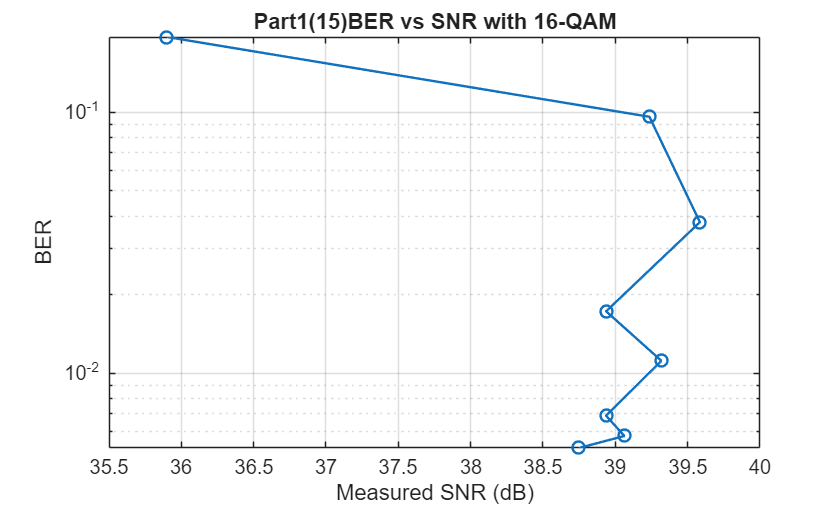

figure('Name','(15) BER vs SNR with clipping');
semilogy(SNRm_vsSNR, BER_vsSNR, 'o-','LineWidth',1.2); grid on;
xlabel('Measured SNR (dB)'); ylabel('BER'); title('Part1(15)BER vs SNR with 16-QAM');

% Part1(16)

Compare the results of 4-QAM and 16-QAM (see below, which is got in past case), we find that 

- For small gain cases, 4-QAM has BER = 0, but 16-QAM has BER > 0. This is because the spaces between symbols in 16-QAM are much smaller than in 4-QAM, so it is more difficult to recognize symbols correctly.

- For small gain cases, the SNR of 4-QAM and 16-QAM are closed.

- In both 4-QAM and 16-QAM cases, clipping effects occur for large gain. The BERs increase significantly and SNRs float between a SNR interval.

4-QAM

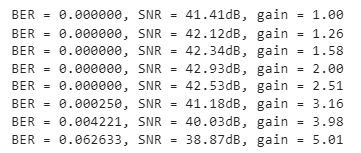

16-QAM

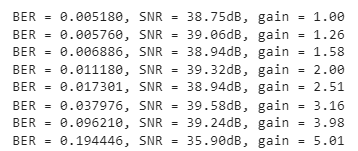

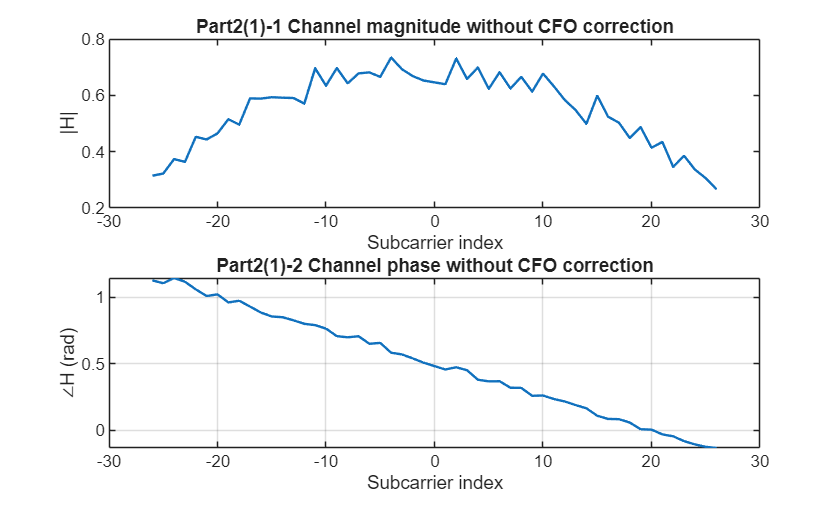

% Part2(1)
L = 64; % length of LTS
fc = 885e6;
delta_f = 5*1e-6 * fc; 

txBits = cell(1, numSym); 
pilotSym  = cell(1, numSym);
txSymTone = cell(1, numSym);  
txSymAll = [];
frame_data = [];
% ======== Generate TX ========   
for nSym = 1:numSym
    Xd = zeros(1, N_fft);
    % pilot: random BPSK
    pilot_bits = randi([0 1], 1, 4);
    pilot_sym  = 1 - 2*pilot_bits;
    Xd(toPos(pilots)) = pilot_sym;
    pilotSym{nSym}    = pilot_sym(:); 

    % data: 4-QAM 
    data_bits = randi([0 1], 48*log2(4), 1);
    txBits{nSym} = data_bits;
    data_sym  = qammod(data_bits, 4, 'InputType','bit', 'UnitAveragePower', true);
    Xd(toPos(data_sc)) = data_sym.';
    txSymTone{nSym} = data_sym(:);        
    txSymAll = [txSymAll; data_sym(:)];   

    x_noCP = ifft(Xd, N_fft);
    x_CP   = [x_noCP(end-N_CP+1:end), x_noCP];
    frame_data = [frame_data, x_CP]; 
end

tx_frame = [Pre_pad, x_STS_10, LTS_block, frame_data, Post_pad];
tx_frame_withCFO = tx_frame(:).* exp(1j*2*pi*delta_f*(0:numel(tx_frame)-1).'/Fs);

rx_length = 2*length(tx_frame_withCFO) ; 
[radio_Tx, radio_Rx] = USRP_init(rx_length);
radio_Tx.InterpolationFactor = 10;
radio_Rx.DecimationFactor = 10;
N_frames = 10;
threshold = 0.002;
N_trans = 2000;
rx_buffer_withCFO = zeros(N_frames ,rx_length) ;
count = 0;
for k = 1:N_trans
    tunderrun = radio_Tx(tx_frame_withCFO(:));       
    [rx_frame, ~, toverflow] = step(radio_Rx); 

    Power = mean(abs(rx_frame).^2);
    if Power > threshold
        count = count + 1;
        rx_buffer_withCFO(count,:) = rx_frame.'; 
    end
    if count == N_frames
        break;
    end
end

f_CFO = rx_buffer_withCFO(5,:);
mf_CFO  = conv(f_CFO(:), h_mf, 'full');  
a_CFO = abs(mf_CFO);
a_CFO_max = max(a_CFO);
candidates = find(abs(mf_CFO)>=0.99*a_CFO_max);
pk_CFO = candidates(1);

start_LTS_noCP_CFO = pk_CFO - (numel(lts2_tmpl) - 1);
start_DATA_CFO  = pk_CFO + 1;

rx_lts_1_CFO = f_CFO(start_LTS_noCP_CFO + (0:L-1));
Rx_LTS_1_CFO = fft(rx_lts_1_CFO, N_fft);
H_LTS1_CFO = Rx_LTS_1_CFO ./ X_lts;

rx_lts_2_CFO = f_CFO(start_LTS_noCP_CFO + L + (0:L-1));
Rx_LTS_2_CFO = fft(rx_lts_2_CFO, N_fft);
H_LTS2_CFO   = Rx_LTS_2_CFO ./ X_lts;

H_est_CFO = 0.5 * (H_LTS1_CFO + H_LTS2_CFO);          
H_est_data_CFO = H_est_CFO(toPos(data_sc)).'; 

figure;
subplot(2,1,1);
plot(all_sc, abs(H_est_CFO(toPos(all_sc))), 'LineWidth',1.2);
xlabel('Subcarrier index'); ylabel('|H|');
title('Part2(1)-1 Channel magnitude without CFO correction');

subplot(2,1,2);
plot(all_sc, angle(H_est_CFO(toPos(all_sc))), 'LineWidth',1.2);
xlabel('Subcarrier index'); ylabel('∠H (rad)');
title('Part2(1)-2 Channel phase without CFO correction');
grid on;

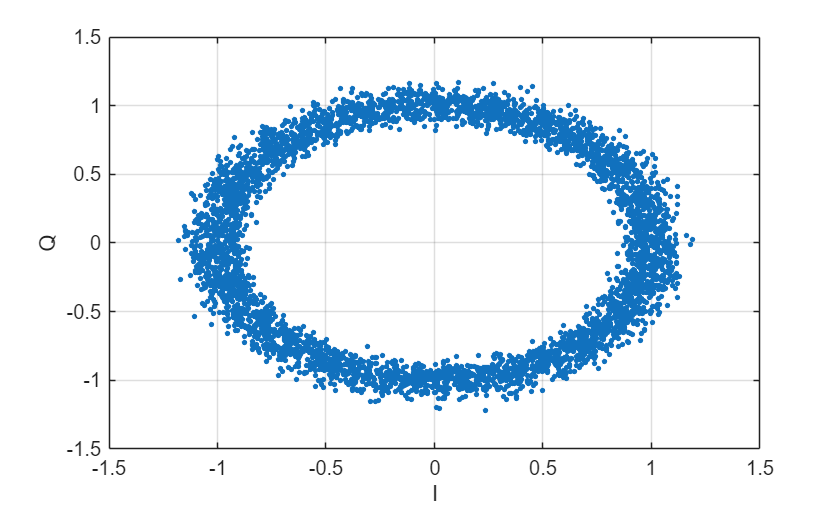

% Part2(2)
idx_DATA_CFO = start_DATA_CFO + (0:LEN_SYM_CP*numSym-1); % numSym = 100
rx_blk_CFO = f_CFO(idx_DATA_CFO);
rx_sym_mat_CFO = reshape(rx_blk_CFO, LEN_SYM_CP, numSym).';
rx_noCP_CFO = rx_sym_mat_CFO(:, N_CP+1:end);
Y_EQ_CFO = []; 

for m = 1:numSym
    rx_sym_CFO = rx_noCP_CFO(m, :);             
    Y_CFO = fft(rx_sym_CFO, N_fft);
    Yd_CFO = Y_CFO(toPos(data_sc)).';
    Ye_CFO = Yd_CFO ./ H_est_data_CFO;
    Y_EQ_CFO = [Y_EQ_CFO; Ye_CFO];
end

figure;
plot(real(Y_EQ_CFO), imag(Y_EQ_CFO), '.', 'MarkerSize',8); hold on; grid on;
xlabel('I'); ylabel('Q');xlim([-1.5 1.5]); ylim([-1.5 1.5]);

% Part2(3)
% use STS (consecutive)
D = 16;                  % STS symbol length

start_STS_CFO = start_LTS_noCP_CFO - 2*N_CP - LEN_STS;   


get_sts_blk = @(k) f_CFO(start_STS_CFO + (k-1)*D + (0:D-1));

s8  = get_sts_blk(8);      
s9  = get_sts_blk(9);
s10 = get_sts_blk(10);


num = sum( s10 .* conj(s9) );       % correlation
phi = angle(num);                   % (-pi, pi]
CFO_hat_consec = phi * Fs / (2*pi*D);

num2 = sum( s10 .* conj(s8) );
phi2 = angle(num2);
CFO_hat_nonconsec = phi2 * Fs / (2*pi*(2*D));   

fprintf('CFO (consecutive 9th-10th) = %.2f Hz\n', CFO_hat_consec);

CFO (consecutive 9th-10th) = 3515.54 Hz


fprintf('CFO (non-consec 8th-10th) = %.2f Hz\n', CFO_hat_nonconsec);

CFO (non-consec 8th-10th) = 3622.11 Hz


% Part2(4)
LTS1 = f_CFO(start_LTS_noCP_CFO + (0:L-1));
LTS2 = f_CFO(start_LTS_noCP_CFO + L + (0:L-1));

num = sum(LTS2 .* conj(LTS1));       
phi = angle(num);
CFO_hat_Hz = phi * Fs / (2*pi*L);    

CFO_error = CFO_hat_Hz - delta_f;

fprintf('Estimated CFO = %.2f Hz\n', CFO_hat_Hz);

Estimated CFO = 4623.93 Hz


fprintf('True added CFO = %.2f Hz\n', delta_f);

True added CFO = 4425.00 Hz


fprintf('CFO estimation error = %.2f Hz\n', CFO_error);

CFO estimation error = 198.93 Hz


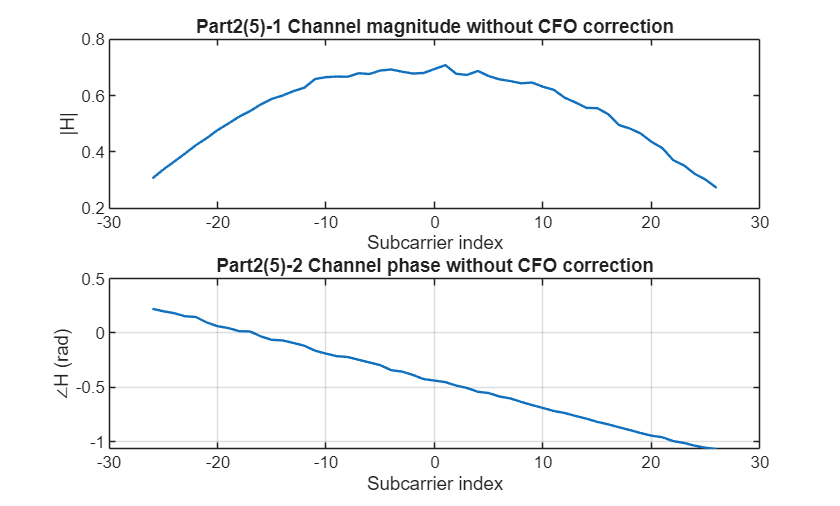

% Part2(5)
f_CFO_corrected = (f_CFO(:).* exp(-1j*2*pi*CFO_hat_Hz*(0:numel(f_CFO)-1).'/Fs)).';
mf_CFO_corrected  = conv(f_CFO_corrected(:), h_mf, 'full');  
a_CFO_corrected = abs(mf_CFO_corrected);
a_CFO_max_corrected = max(a_CFO_corrected);
candidates_corrected = find(abs(mf_CFO_corrected)>=0.99*a_CFO_max_corrected);
pk_CFO_corrected = candidates_corrected(1);

start_LTS_noCP_CFO_corrected = pk_CFO_corrected - (numel(lts2_tmpl) - 1);
start_DATA_CFO_corrected  = pk_CFO_corrected + 1;

rx_lts_1_CFO_corrected = f_CFO_corrected(start_LTS_noCP_CFO_corrected + (0:L-1));
Rx_LTS_1_CFO_corrected = fft(rx_lts_1_CFO_corrected, N_fft);
H_LTS1_CFO_corrected = Rx_LTS_1_CFO_corrected ./ X_lts;

rx_lts_2_CFO_corrected = f_CFO_corrected(start_LTS_noCP_CFO_corrected + L + (0:L-1));
Rx_LTS_2_CFO_corrected = fft(rx_lts_2_CFO_corrected, N_fft);
H_LTS2_CFO_corrected   = Rx_LTS_2_CFO_corrected ./ X_lts;

H_est_CFO_corrected = 0.5 * (H_LTS1_CFO_corrected + H_LTS2_CFO_corrected);          
H_est_data_CFO_corrected = H_est_CFO_corrected(toPos(data_sc)).'; 

figure;
subplot(2,1,1);
plot(all_sc, abs(H_est_CFO_corrected(toPos(all_sc))), 'LineWidth',1.2);
xlabel('Subcarrier index'); ylabel('|H|');
title('Part2(5)-1 Channel magnitude without CFO correction');

subplot(2,1,2);
plot(all_sc, angle(H_est_CFO_corrected(toPos(all_sc))), 'LineWidth',1.2);
xlabel('Subcarrier index'); ylabel('∠H (rad)');
title('Part2(5)-2 Channel phase without CFO correction');
grid on;

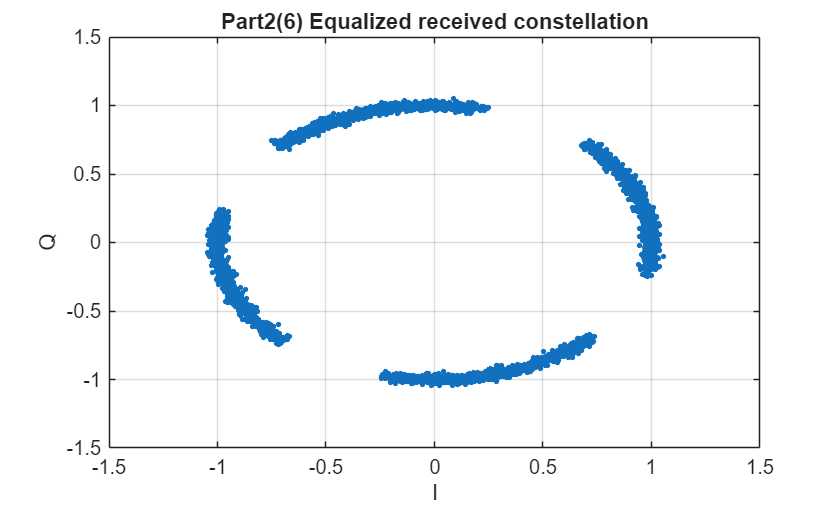

% Part2(6)
idx_DATA_CFO_corrected = start_DATA_CFO_corrected + (0:LEN_SYM_CP*numSym-1); % numSym = 100
rx_blk_CFO_corrected = f_CFO_corrected(idx_DATA_CFO_corrected);
rx_sym_mat_CFO_corrected = reshape(rx_blk_CFO_corrected, LEN_SYM_CP, numSym).';
rx_noCP_CFO_corrected = rx_sym_mat_CFO_corrected(:, N_CP+1:end);
Y_EQ_CFO_corrected = []; 

for m = 1:numSym
    rx_sym_CFO_corrected = rx_noCP_CFO_corrected(m, :);             
    Y_CFO_corrected = fft(rx_sym_CFO_corrected, N_fft);
    Yd_CFO_corrected = Y_CFO_corrected(toPos(data_sc)).';
    Ye_CFO_corrected = Yd_CFO_corrected ./ H_est_data_CFO_corrected;
    Y_EQ_CFO_corrected = [Y_EQ_CFO_corrected; Ye_CFO_corrected];
end

figure;
plot(real(Y_EQ_CFO_corrected), imag(Y_EQ_CFO_corrected), '.', 'MarkerSize',8); hold on; grid on;
xlabel('I'); ylabel('Q');xlim([-1.5 1.5]); ylim([-1.5 1.5]);
title('Part2(6) Equalized received constellation');

We observed that the phase shift is partially corrected; however, some residual CFO remains, causing the constellation to rotate.

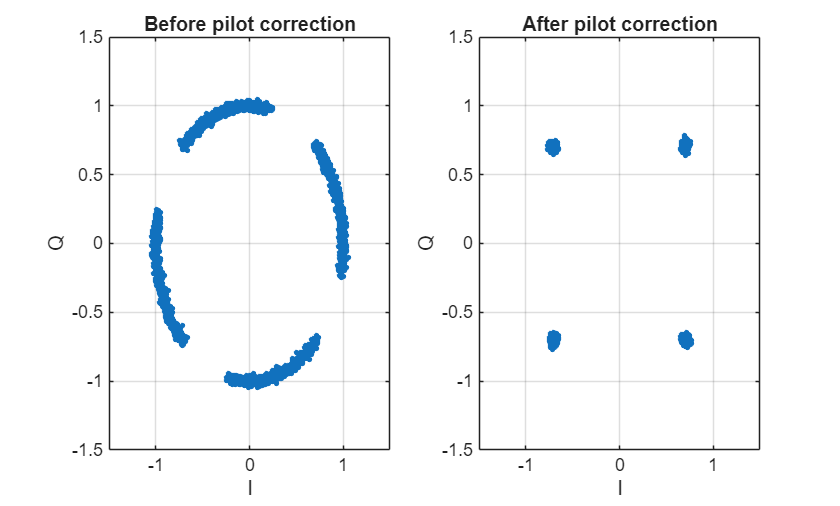

% Part2 (7)
pilot_sc = [-21, -7, 7, 21];
pilot_pos = toPos(pilot_sc);      % pilot 的頻域索引


idx_DATA = start_DATA_CFO_corrected + (0:LEN_SYM_CP*numSym-1);
rx_blk = f_CFO_corrected(idx_DATA);                     
rx_sym_mat = reshape(rx_blk, LEN_SYM_CP, numSym).';     
rx_noCP = rx_sym_mat(:, N_CP+1:end);                    

phi_pilot_per_sym = zeros(1, numSym);
phi_pilot_smooth  = zeros(1, numSym);
Y_EQ_pilot_corrected = [];

for m = 1:numSym
    
    rx_sym = rx_noCP(m, :);
    Y_sym = fft(rx_sym, N_fft);
    Y_sym_shift = fftshift(Y_sym);

    % CE
    Y_all    = Y_sym(toPos(all_sc));
    H_all    = H_est_CFO_corrected(toPos(all_sc));
    H_shift = fftshift(H_est_CFO_corrected);
    toPosShifted = @(sc) mod(sc + N_fft/2, N_fft) + 1;

    idx_all_s = toPosShifted(all_sc);
    Y_all_s   = Y_sym_shift(idx_all_s);
    H_all_s   = H_shift(idx_all_s);
    Y_eq_all  = Y_all_s ./ H_all_s;

    
    [~, pilot_pos_52] = ismember(pilot_sc, all_sc);
    Rp = Y_eq_all(pilot_pos_52);     
    Rp = Rp(:).';                 
    P_known = pilotSym{m}(:);    
   
    phi_inst = angle( Rp * conj(P_known) );   
    phi_pilot_per_sym(m) = phi_inst;
    
    
    Y_eq_all_corrected = Y_eq_all * exp(-1j *phi_inst);
    Yd_corrected = Y_eq_all_corrected( ismember(all_sc, data_sc) );
    Yd_corrected = Yd_corrected(:);
    Y_EQ_pilot_corrected = [Y_EQ_pilot_corrected; Yd_corrected];
end



figure;
subplot(1,2,1);
plot(real(Y_EQ_CFO_corrected), imag(Y_EQ_CFO_corrected), '.', 'MarkerSize',8);
title('Before pilot correction'); xlabel('I'); ylabel('Q'); grid on;
xlim([-1.5 1.5]); ylim([-1.5 1.5]);

subplot(1,2,2);
plot(real(Y_EQ_pilot_corrected), imag(Y_EQ_pilot_corrected), '.', 'MarkerSize',8);
title('After pilot correction'); xlabel('I'); ylabel('Q'); grid on;
xlim([-1.5 1.5]); ylim([-1.5 1.5]);

% Part2 (8)
L = 64; % length of LTS
fc = 885e6;
trueCFO = zeros(1,10);
estCFO  = zeros(1,10);
estCFO_LTS = zeros(1,10);
for i = 1:10
    theta = zeros(1,numSym);
    theta = theta(:);
    delta_f = 5*i*1e-6 * fc;
    trueCFO(i) = delta_f;
    
    tx_frame_withCFO = tx_frame(:).* exp(1j*2*pi*delta_f*(0:numel(tx_frame)-1).'/Fs);
    
    rx_length = 2*length(tx_frame_withCFO) ; 
    [radio_Tx, radio_Rx] = USRP_init(rx_length);
    radio_Tx.InterpolationFactor = 10;
    radio_Rx.DecimationFactor = 10;
    N_frames = 10;
    threshold = 0.002;
    N_trans = 2000;
    rx_buffer_withCFO = zeros(N_frames ,rx_length) ;
    count = 0;
    for k = 1:N_trans
        tunderrun = radio_Tx(tx_frame_withCFO(:));       
        [rx_frame, ~, toverflow] = step(radio_Rx); 
    
        Power = mean(abs(rx_frame).^2);
        if Power > threshold
            count = count + 1;
            rx_buffer_withCFO(count,:) = rx_frame.'; 
        end
        if count == N_frames
            break;
        end
    end
    for ii = 2:10
        f_CFO = rx_buffer_withCFO(ii,:);
        
        LTS1 = f_CFO(start_LTS_noCP_CFO + (0:L-1));
        LTS2 = f_CFO(start_LTS_noCP_CFO + L + (0:L-1));
        
        num = sum(LTS2 .* conj(LTS1));       
        phi = angle(num);
        CFO_hat_Hz = phi * Fs / (2*pi*L); 
        f_CFO_corrected = (f_CFO(:).* exp(-1j*2*pi*CFO_hat_Hz*(0:numel(f_CFO)-1).'/Fs)).';
        mf_CFO_corrected  = conv(f_CFO_corrected(:), h_mf, 'full');  
        a_CFO_corrected = abs(mf_CFO_corrected);
        a_CFO_max_corrected = max(a_CFO_corrected);
        candidates_corrected = find(abs(mf_CFO_corrected)>=0.99*a_CFO_max_corrected);
        pk_CFO_corrected = candidates_corrected(1);
        
        start_LTS_noCP_CFO_corrected = pk_CFO_corrected - (numel(lts2_tmpl) - 1);
        start_DATA_CFO_corrected  = pk_CFO_corrected + 1;
        if start_DATA_CFO_corrected < numel(f) - LEN_SYM_CP*numSym
                break;
        end
    end

    rx_lts_1_CFO_corrected = f_CFO_corrected(start_LTS_noCP_CFO_corrected + (0:L-1));
    Rx_LTS_1_CFO_corrected = fft(rx_lts_1_CFO_corrected, N_fft);
    H_LTS1_CFO_corrected = Rx_LTS_1_CFO_corrected ./ X_lts;
    
    rx_lts_2_CFO_corrected = f_CFO_corrected(start_LTS_noCP_CFO_corrected + L + (0:L-1));
    Rx_LTS_2_CFO_corrected = fft(rx_lts_2_CFO_corrected, N_fft);
    H_LTS2_CFO_corrected   = Rx_LTS_2_CFO_corrected ./ X_lts;
    
    H_est_CFO_corrected = 0.5 * (H_LTS1_CFO_corrected + H_LTS2_CFO_corrected);          
    H_est_data_CFO_corrected = H_est_CFO_corrected(toPos(data_sc)).'; 
    idx_DATA_CFO_corrected = start_DATA_CFO_corrected + (0:LEN_SYM_CP*numSym-1); % numSym = 100
    rx_blk_CFO_corrected = f_CFO_corrected(idx_DATA_CFO_corrected);
    rx_sym_mat_CFO_corrected = reshape(rx_blk_CFO_corrected, LEN_SYM_CP, numSym).';
    rx_noCP_CFO_corrected = rx_sym_mat_CFO_corrected(:, N_CP+1:end);
    Y_EQ_CFO_corrected = []; 
    
    for m = 1:numSym
        rx_sym_CFO_corrected = rx_noCP_CFO_corrected(m, :);             
        Y_CFO_corrected = fft(rx_sym_CFO_corrected, N_fft);
        Yd_CFO_corrected = Y_CFO_corrected(toPos(data_sc)).';
        Ye_CFO_corrected = Yd_CFO_corrected ./ H_est_data_CFO_corrected;
        Y_EQ_CFO_corrected = [Y_EQ_CFO_corrected; Ye_CFO_corrected];
    end
    idx_DATA = start_DATA_CFO_corrected + (0:LEN_SYM_CP*numSym-1);
    rx_blk = f_CFO_corrected(idx_DATA);                     
    rx_sym_mat = reshape(rx_blk, LEN_SYM_CP, numSym).';    
    rx_noCP = rx_sym_mat(:, N_CP+1:end);                    
    
    phi_pilot_per_sym = zeros(1, numSym);
    phi_pilot_smooth  = zeros(1, numSym);
    Y_EQ_pilot_corrected = [];
    
    for m = 1:numSym
        
        rx_sym = rx_noCP(m, :);
        Y_sym = fft(rx_sym, N_fft);
        Y_sym_shift = fftshift(Y_sym);
    
        % CE
        Y_all    = Y_sym(toPos(all_sc));
        H_all    = H_est_CFO_corrected(toPos(all_sc));

        toPosShifted = @(sc) mod(sc + N_fft/2, N_fft) + 1;
    
        idx_all_s = toPosShifted(all_sc);
        Y_all_s   = Y_sym_shift(idx_all_s);
        H_all_s   = H_shift(idx_all_s);
        Y_eq_all  = Y_all_s ./ H_all_s;
    
       
        [~, pilot_pos_52] = ismember(pilot_sc, all_sc);
        Rp = Y_eq_all(pilot_pos_52);     
        Rp = Rp(:).';                
        P_known = pilotSym{m}(:);     

        phi_inst = angle( Rp * conj(P_known) );   
        phi_pilot_per_sym(m) = phi_inst;
        theta(m) = phi_inst;
        
        
        Y_eq_all_corrected = Y_eq_all * exp(-1j *phi_inst);
        
        Yd_corrected = Y_eq_all_corrected( ismember(all_sc, data_sc) );
        Yd_corrected = Yd_corrected(:);
        Y_EQ_pilot_corrected = [Y_EQ_pilot_corrected; Yd_corrected] ;      

    end
    Tsym = (N_fft + N_CP) / Fs;         
    t_symbol    = (0:numSym-1).' * Tsym;       
    th = unwrap(theta);                  
    p  = polyfit(t_symbol, th, 1);               % th ≈ p(1)*t + p(2)
    f_residual_Hz = p(1) / (2*pi);
    estCFO(i) = f_residual_Hz + CFO_hat_Hz;
    estCFO_LTS(i) = CFO_hat_Hz;
    
end

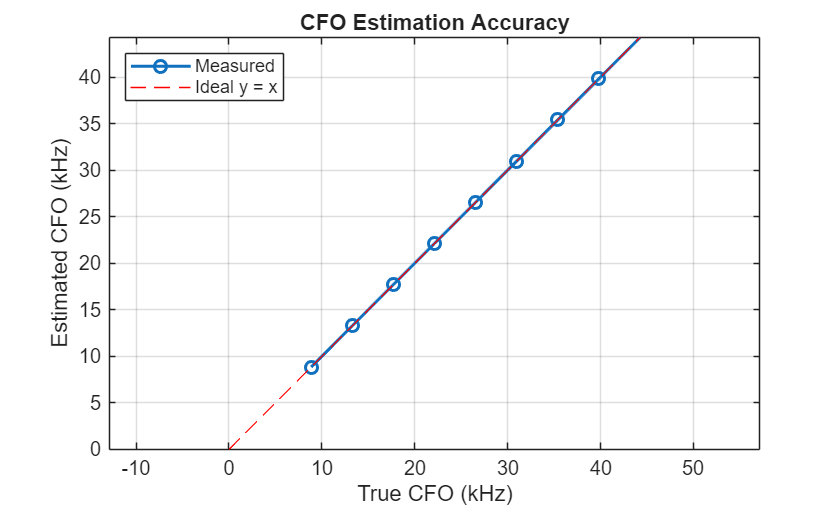

figure;
plot(trueCFO(2:10)/1e3, estCFO(2:10)/1e3, 'o-', 'LineWidth',1.5, 'MarkerSize',6);
grid on;
xlabel('True CFO (kHz)');
ylabel('Estimated CFO (kHz)');
title('CFO Estimation Accuracy');
xlim([0 max(trueCFO)/1e3]);
ylim([0 max(trueCFO)/1e3]);
axis equal; hold on;
% plot(trueCFO/1e3, estCFO_LTS/1e3, 'o-', 'LineWidth',1.5, 'MarkerSize',6);hold on;
plot([0 max(trueCFO)/1e3], [0 max(trueCFO)/1e3], 'r--'); % ideal line
legend('Measured','Ideal y = x', 'Location','northwest');

The maximum CFO frequency that can ensure estimation accuracy is 50ppm. 

% Part2(9)

The algorithm first uses LTS to estimate CFO, and we use this estimated CFO to do rough correction by $\Delta \hat{f} = \frac{\hat{\phi}}{2\pi T}$

Next, use the mean phase differences of pilot tones for each symbol to compute CFO residual and apply finer correction.